clc
clear 
rng(2024)
% 按照设定相位初始化卫星队列
sat_num=9;
for k = 1:sat_num
    sat_index(1,k) = 0 + (k-1)*15; % initial phase index
end
sat_array=gen_satellite_array_by_index(sat_index);


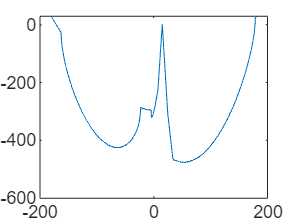


% 重新设定时间分辨率
h=1;
days=1;
for i=1:sat_num
    sat_array{i}=sat_array{i}.set_time_parameters(days,h);
    sat_array{i}=sat_array{i}.update();
end


gama=0.01;
fun=@(x)cal_ob_fun(x,sat_array,1,gama);
x0=0;
varn=1;

x=linspace(-180,180,1000);
parfor i=1:length(x)
    a(i)=fun(x(i));
end
plot(x,a)

% % fminbnd方法
tic
% options = optimset('Display','iter');
[x,fval] = fminbnd(fun,-180,180)

x = 53.7069

fval = -477.1557

toc

历时 0.698173 秒。



tic

% 设置非默认求解器选项
options4 = optimoptions("surrogateopt","PlotFcn",[]);

% 求解
[x,fval] = surrogateopt(fun,repmat(-15,varn,1),repmat(15,...
    varn,1),[],[],[],[],[],options4);

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.



% 清除变量
clearvars options4
toc

历时 13.572195 秒。


x

x = -2.9531

fval

fval = -320.9128